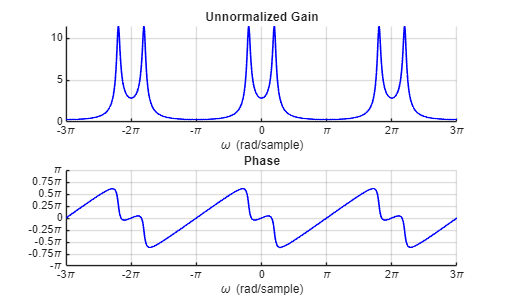

w = linspace(-3*pi, 3*pi, 1001);
% from y[n] = 1.5y[n-1] - 0.85y[n-2] + x[]
%b = 1;
%a = [1 -1.5 0.85];
%H = freqz(b, a, w);
H = 1 ./ (1 - 1.5*exp(-1i*w) + 0.85*exp(-1i*2*w));

figure(1)
% Magnitude
A = subplot(2,1,1);
line(w, abs(H), 'Color', 'b', 'LineWidth', 1.2);
set(A, 'XLim', [w(1) w(end)]);
xlabel('\omega (rad/sample)')
title('Unnormalized Gain')
grid on
xticks([-3*pi -2*pi -pi 0 pi 2*pi 3*pi])
xticklabels({'-3\pi','-2\pi','-\pi','0','\pi','2\pi','3\pi'})

% Phase
A = subplot(2,1,2);
line(w, angle(H), 'Color', 'b', 'LineWidth', 1.2);
set(A, 'XLim', [w(1) w(end)], 'YLim', [-pi pi]);
xlabel('\omega (rad/sample)')
title('Phase')
grid on
xticks([-3*pi -2*pi -pi 0 pi 2*pi 3*pi])
xticklabels({'-3\pi','-2\pi','-\pi','0','\pi','2\pi','3\pi'})
yticks([-pi -0.75*pi -0.5*pi -0.25*pi 0 0.25*pi 0.5*pi 0.75*pi pi])
yticklabels({'-\pi','-0.75\pi','-0.5\pi','-0.25\pi','0','0.25\pi','0.5\pi','0.75\pi','\pi'})

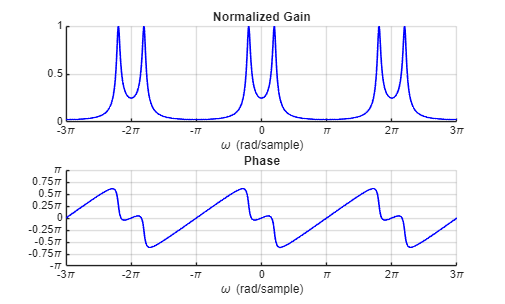


Nor_H = abs(H) / max(abs(H));
figure(2)
% Magnitude
A = subplot(2,1,1);
line(w, Nor_H, 'Color', 'b', 'LineWidth', 1.2);
set(A, 'XLim', [w(1) w(end)]);
xlabel('\omega (rad/sample)')
title('Normalized Gain')
grid on
xticks([-3*pi -2*pi -pi 0 pi 2*pi 3*pi])
xticklabels({'-3\pi','-2\pi','-\pi','0','\pi','2\pi','3\pi'})

% Phase
A = subplot(2,1,2);
line(w, angle(H), 'Color', 'b', 'LineWidth', 1.2);
set(A, 'XLim', [w(1) w(end)], 'YLim', [-pi pi]);
xlabel('\omega (rad/sample)')
title('Phase')
grid on
xticks([-3*pi -2*pi -pi 0 pi 2*pi 3*pi])
xticklabels({'-3\pi','-2\pi','-\pi','0','\pi','2\pi','3\pi'})
yticks([-pi -0.75*pi -0.5*pi -0.25*pi 0 0.25*pi 0.5*pi 0.75*pi pi])
yticklabels({'-\pi','-0.75\pi','-0.5\pi','-0.25\pi','0','0.25\pi','0.5\pi','0.75\pi','\pi'})

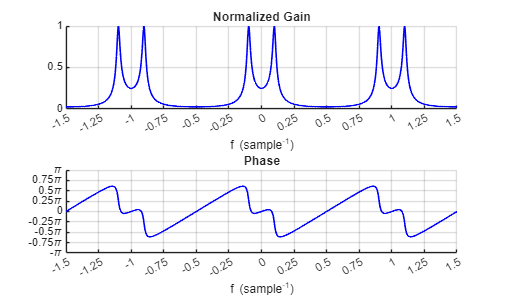


figure(3)
% Magnitude
A = subplot(2,1,1);
f = w ./ (2*pi);
line(f, Nor_H, 'Color', 'b', 'LineWidth', 1.2);
set(A, 'XLim', [f(1) f(end)]);
xlabel('f (sample^{-1})')
title('Normalized Gain')
grid on
set(gca, 'XTick', [-1.5 1.5])
set(gca,'XTick',[-1.5 -1.25 -1 -0.75 -0.5 -0.25 0 0.25 0.5 0.75 1 1.25 1.5])

% Phase
A = subplot(2,1,2);
line(f, angle(H), 'Color', 'b', 'LineWidth', 1.2);
set(A, 'XLim', [f(1) f(end)], 'YLim', [-pi pi]);
xlabel('f (sample^{-1})')
title('Phase')
grid on
set(gca, 'XTick', [-1.5 1.5])
set(gca,'XTick',[-1.5 -1.25 -1 -0.75 -0.5 -0.25 0 0.25 0.5 0.75 1 1.25 1.5])
yticks([-pi -0.75*pi -0.5*pi -0.25*pi 0 0.25*pi 0.5*pi 0.75*pi pi])
yticklabels({'-\pi','-0.75\pi','-0.5\pi','-0.25\pi','0','0.25\pi','0.5\pi','0.75\pi','\pi'})

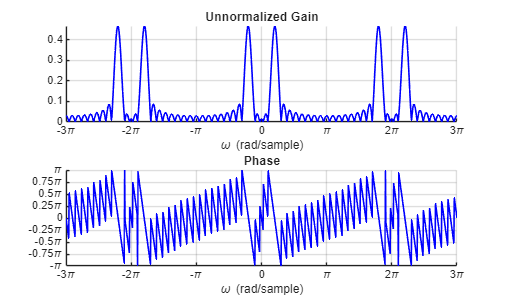


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

load("FIR.mat");
H_FIR = 0;
for n = 1:length(hn)
    H_FIR = H_FIR + hn(n) * exp(-1i*w*(n-1));
end

figure(4)
% Magnitude
A = subplot(2,1,1);
line(w, abs(H_FIR), 'Color', 'b', 'LineWidth', 1.2);
set(A, 'XLim', [w(1) w(end)]);
xlabel('\omega (rad/sample)')
title('Unnormalized Gain')
grid on
xticks([-3*pi -2*pi -pi 0 pi 2*pi 3*pi])
xticklabels({'-3\pi','-2\pi','-\pi','0','\pi','2\pi','3\pi'})

% Phase
A = subplot(2,1,2);
line(w, angle(H_FIR), 'Color', 'b', 'LineWidth', 1.2);
set(A, 'XLim', [w(1) w(end)], 'YLim', [-pi pi]);
xlabel('\omega (rad/sample)')
title('Phase')
grid on
xticks([-3*pi -2*pi -pi 0 pi 2*pi 3*pi])
xticklabels({'-3\pi','-2\pi','-\pi','0','\pi','2\pi','3\pi'})
yticks([-pi -0.75*pi -0.5*pi -0.25*pi 0 0.25*pi 0.5*pi 0.75*pi pi])
yticklabels({'-\pi','-0.75\pi','-0.5\pi','-0.25\pi','0','0.25\pi','0.5\pi','0.75\pi','\pi'})

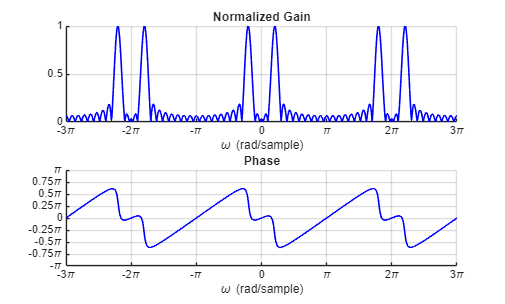


Nor_H_FIR = abs(H_FIR) / max(abs(H_FIR));
figure(5)
% Magnitude
A = subplot(2,1,1);
line(w, Nor_H_FIR, 'Color', 'b', 'LineWidth', 1.2);
set(A, 'XLim', [w(1) w(end)]);
xlabel('\omega (rad/sample)')
title('Normalized Gain')
grid on
xticks([-3*pi -2*pi -pi 0 pi 2*pi 3*pi])
xticklabels({'-3\pi','-2\pi','-\pi','0','\pi','2\pi','3\pi'})

% Phase
A = subplot(2,1,2);
line(w, angle(H), 'Color', 'b', 'LineWidth', 1.2);
set(A, 'XLim', [w(1) w(end)], 'YLim', [-pi pi]);
xlabel('\omega (rad/sample)')
title('Phase')
grid on
xticks([-3*pi -2*pi -pi 0 pi 2*pi 3*pi])
xticklabels({'-3\pi','-2\pi','-\pi','0','\pi','2\pi','3\pi'})
yticks([-pi -0.75*pi -0.5*pi -0.25*pi 0 0.25*pi 0.5*pi 0.75*pi pi])
yticklabels({'-\pi','-0.75\pi','-0.5\pi','-0.25\pi','0','0.25\pi','0.5\pi','0.75\pi','\pi'})

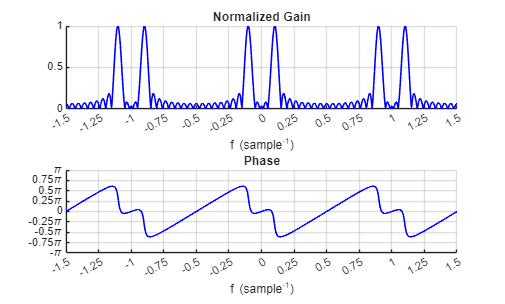


figure(6)
% Magnitude
A = subplot(2,1,1);
f = w ./ (2*pi);
line(f, Nor_H_FIR, 'Color', 'b', 'LineWidth', 1.2);
set(A, 'XLim', [f(1) f(end)]);
xlabel('f (sample^{-1})')
title('Normalized Gain')
grid on
set(gca, 'XTick', [-1.5 1.5])
set(gca,'XTick',[-1.5 -1.25 -1 -0.75 -0.5 -0.25 0 0.25 0.5 0.75 1 1.25 1.5])

% Phase
A = subplot(2,1,2);
line(f, angle(H), 'Color', 'b', 'LineWidth', 1.2);
set(A, 'XLim', [f(1) f(end)], 'YLim', [-pi pi]);
xlabel('f (sample^{-1})')
title('Phase')
grid on
set(gca, 'XTick', [-1.5 1.5])
set(gca,'XTick',[-1.5 -1.25 -1 -0.75 -0.5 -0.25 0 0.25 0.5 0.75 1 1.25 1.5])
yticks([-pi -0.75*pi -0.5*pi -0.25*pi 0 0.25*pi 0.5*pi 0.75*pi pi])
yticklabels({'-\pi','-0.75\pi','-0.5\pi','-0.25\pi','0','0.25\pi','0.5\pi','0.75\pi','\pi'})